SimulationName='simulation_lifetime_simulationVSexperiment_20220719_dpt';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

cd(savefolder)
mkdir(SimulationName)

filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_lifetime_simulationVSexperiment_20220719_dpt/'

cd(filepath)

spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat',1)

Reading /Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat




% then do fitting. fitting range 1 to 12.5


fitting=spc.fits;
save('fitting_PKA_dpt0','fitting')

cd(filepath)
copyfile /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat prf_PKA.mat
load('prf_PKA.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_PKA=find(prf_interp1==max(prf_interp1))

prf_peak_PKA = 39

find(prf==max(prf))

ans = 38

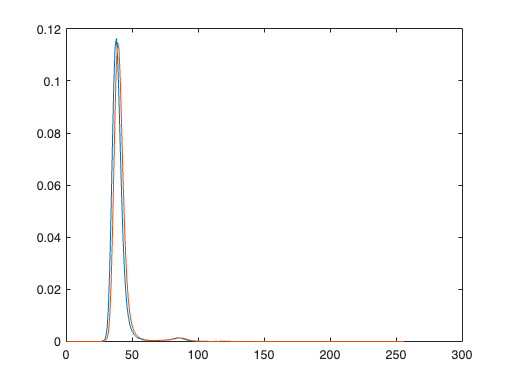

figure
plot(prf)
hold on
plot(prf_interp1)

prf=prf_interp1;
prf_interp1_name='prf_PKA_interp1.mat';
save(prf_interp1_name,'prf')

prf_name='prf_PKA_shifted.mat'

prf_name = 'prf_PKA_shifted.mat'

load('prf_PKA.mat')
prf_original=prf;
prf=zeros(1,256);

for i=2:256
    prf(i)=prf_original(i-1);
end

prf(1)=prf_original(256);

save(prf_name,'prf')

p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6701

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3299

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0708

SHG=spc.fits{1,1}.beta6

SHG = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.9355

backcorr=spc.fits{1,1}.backCorr

backcorr = 146.9438


lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     20   256


weight_n_lft=lft_steps(range(1):range(2)).*spc.lifetimes{1}(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_PKA = 3.9043

samplesize_PKA=sum(spc.lifetimes{1})

samplesize_PKA = 2020773

n_exp_PKA=spc.lifetimes{1};

lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

weight_n_lft=lft_steps(range(1):range(2)).*spc.fits{1,1}.curve';
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_PKA = 3.8884

tau1_PKA=2.14

tau1_PKA = 2.1400

tau2_PKA=0.69

tau2_PKA = 0.6900

PKA_PopulationName='PKA_population_20220719'

PKA_PopulationName = 'PKA_population_20220719'

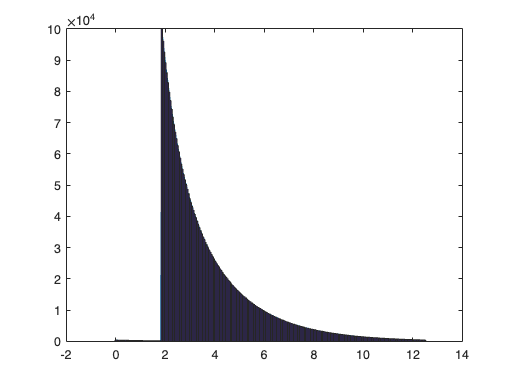

     3417460



GenPop256_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

save('PKA_simulation_parameters_20220719','tau1_PKA','tau2_PKA','p1_PKA','p2_PKA','samplesize_PKA','empirical_lft_PKA','n_exp_PKA','prf_peak_PKA','delta_peak_time','prf')

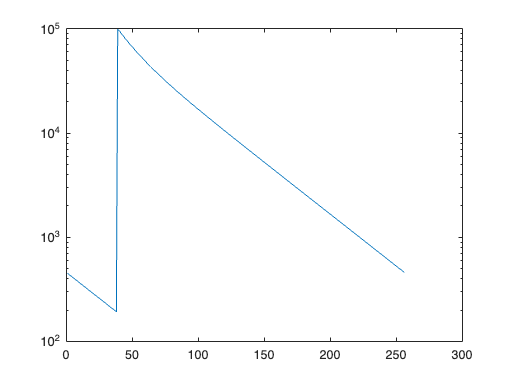

load(PKA_PopulationName)
figure
semilogy(counts)

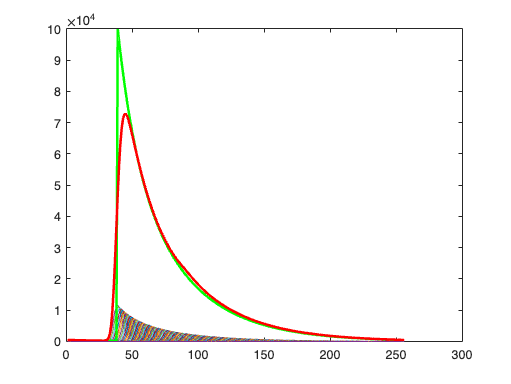

x_i=(1:1:256)-prf_peak_PKA;
x=x_i*(12.5/256);
xsim=linspace(0,12.5,256);
[n,xout]=hist(Population, xsim);
load(prf_name)
    
for i=1:256
    eval(['n_c_',num2str(i),'=zeros(1,256);'])
    n_i = n(i)*prf;
    x_c=x_i+i; 
    
    for j=1:size(x_c,2)
        if x_c(j)<=0
           x_c(j)=x_c(j)+256;  
        end
        
        if x_c(j)>256
            x_c(j)=x_c(j)-256;
        end
        
    end
    eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
end
figure
xlabel('Channels')
ylabel('Photon Count')
for i=1:256
    eval(['plot(n_c_',num2str(i),')'])
    hold on
end
plot(n,'LineWidth',2,'Color','g')
hold on

n_c=zeros(1,256);
for i=1:256
    eval(['this_n=n_c_',num2str(i),';'])
    n_c=[n_c;this_n];
end
n_c_all=sum(n_c);
% eval(['hist_prf2_',num2str(k),'=n_c_all;'])

plot(n_c_all,'LineWidth',2,'Color','r');
hold off




n_c_all_norm=n_c_all/max(n_c_all);

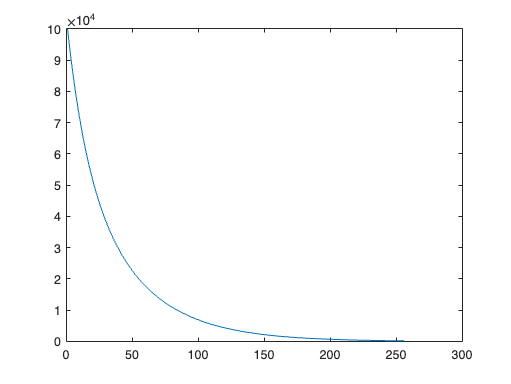

n_to_conv=zeros(1,256);
n_to_conv(1:256-prf_peak_PKA+1)=n(prf_peak_PKA:256);
n_to_conv(256-prf_peak_PKA+2:256)=n(1:prf_peak_PKA-1);
figure
plot(n_to_conv)


conv_n=conv(n_to_conv,prf)
conv_n1=conv_n(257:length(conv_n));
conv_n_final=conv_n(1:256);
conv_n_final(1:length(conv_n1))=conv_n(1:length(conv_n1))+conv_n1;

conv_n = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0035    0.0098    0.0273    0.0783    0.2107    0.4937    0.9798    1.7000    2.6177    3.6492    4.6757    5.5884    6.3060    6.8041    7.1109    7.2550    7.2763    7.2153    7.0993    6.9497    6.7809    6.6017


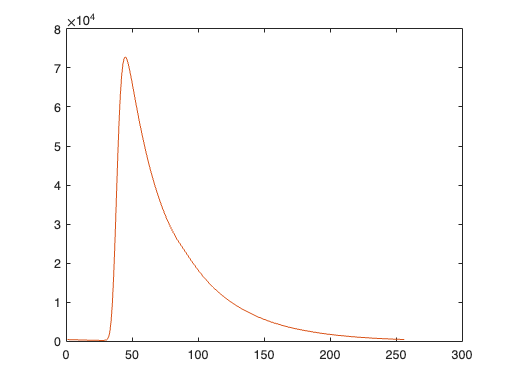


figure
plot(conv_n_final)
hold on
plot(n_c_all)


% These two convolution method gives exactly the same result

% now do the simulation from the population.
% before that define the autofluorescence first.
copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat


mkdir([filepath,'/PKA_sensoronly_0719_2/']);


AF=0; % autofluorescence size depending on the pixel numbers of the roi (autofluorescence photon of the whole view in total is 25487)

for j=1:50
    FLIMsim256_Ach_noauto(samplesize_PKA,0,AF,prf_peak_PKA,PKA_PopulationName, prf_interp1_name, 'autofluorescence.mat'); % no DC
    load('FLIMSimulation_pm.mat')
    samplename=[filepath,'/PKA_sensoronly_0719_2/',num2str(j)];
    save(samplename,'n','xout');
end

chan=1;
lft_steps=(1:1:256)*12.5/256;
weight_n_lft=lft_steps.*n_c_all;
empirical_lft_analytical=sum(weight_n_lft)/sum(n_c_all)

empirical_lft_analytical = 3.8239


    cd([filepath,'/PKA_sensoronly_0719/']);
    matfiles = dir('*.mat');
    
    p=[];
    TauTrunc=[];
    chi2=[];
    avgTau=[];
    emp_lft=[];
    emp_lftTrunc=[];
    offsets=[];
    deltapeaktimes=[];
    back_corrections=[];
    
    
    
    for j=1:15
        filename = matfiles(j).name;
        load(filename);
        n=n+backcorr;
        
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        
        weight_n_lft=lft_steps.*n;
%         empirical_lft=sum(weight_n_lft)/sum(n)+(figureoffset-spc.switchess{1,1}.figOffset); % prf peak at 53. 53*12.5/256=2.5879
        empirical_lft=sum(weight_n_lft)/sum(n);

        p(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3); %p1
        TauTrunc(j)=spc.fits{chan}.avgTauTrunc;%empirical lifetime; ; did not use spc_calcEmpiricalMean(chan) because the offset is not calculated every single time.
        chi2(j)=spc.fits{chan}.redchisq; %chi2
        avgTau(j)=spc.fits{chan}.avgTau; % mean Tau calculated from fit
        emp_lft(j)=empirical_lft; % empirical lft
        emp_lftTrunc(j)=spc.fits{chan}.EmpTauTrunc; %empTau truncated
        offsets(j)=spc.switchess{1,1}.figOffset;
        deltapeaktimes(j)=spc.fits{1,1}.beta5;
        back_corrections(j)=spc.fits{1,1}.backCorr;
    end

fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0
fraction of photons from SHG: 0


fraction of photons from SHG: 0
